# METODO DE LA SECANTE 

clc, clear;
format long g;
syms x;

**INGRESAR EL X DE DATO INFERIOR:**

Lim_inf = 0;

**INGRESAR EL X DE DATO SUPERIOR:**

Lim_sup = 5;

**INGRESAR LA TOLERACIA:**

Tol     = 0.00001;

**INGRESAR EL NUMERO DE ITERACIONES:**

Num_it  = 20;

**INGRESAR LA ECUACÍON F(x):**

f_x= -1.654*0.44+9.36*log10(x+1)-0.2+ ( (log10(1.7/(4.2-1.5)))/ (0.4+ 1094/(x+1)^5.19) )+2.32*log10(16246.71)-8.07-log10(2.35*10^7);
%f_x= cos(x)-x;

**=========================================================================================================================**

**=========================================================================================================================**

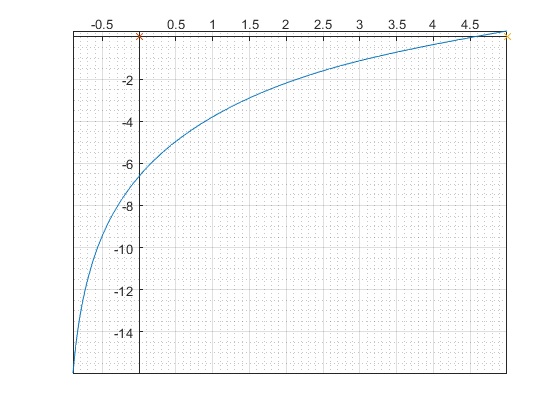

fplot(f_x);
hold on;
plot(Lim_inf,0,'x');
plot(Lim_sup,0,'x');
hold off;
grid on;
grid minor;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

f= @(x) eval(f_x);
i=1;
q_0=f(Lim_inf)

q_0 =           -6.6000356526584


q_1=f(Lim_sup)

q_1 =          0.281890273459963



while(i<=Num_it)
    
    p=Lim_sup-(q_1*(Lim_sup-Lim_inf)/(q_1-q_0));
   
    if(abs(p-Lim_sup)<Tol )
        disp(p);    
        break;
    else
        Lim_inf=Lim_sup;
        q_0=q_1;
        Lim_sup=p;
        q_1=f(p);
        
    end
    i=i+1;
end

           4.5477461821177

